lambda = 400:1:700;
addpath("nm to RGB")

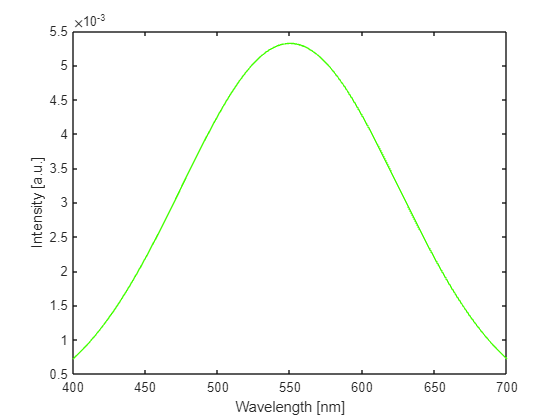


wav_center =550;
sigma = 75;

intesity = normpdf(lambda, wav_center, sigma);

color = spectrumRGB(wav_center);

figure
plot(lambda,intesity,Color=color)
xlabel("Wavelength [nm]")
ylabel("Intensity [a.u.]")

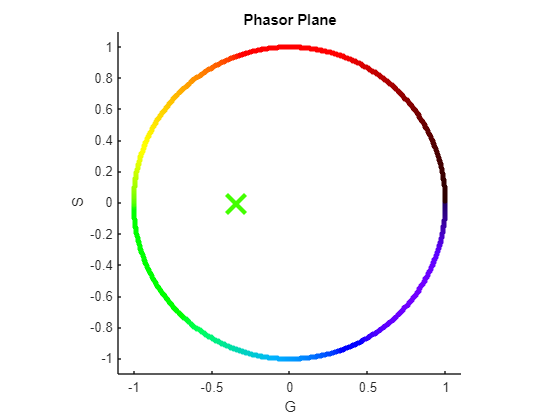


spectrum = zeros(numel(lambda),2);
spectrum(:,1) = lambda;
spectrum(:,2) = intesity;

figure;
cerchio = ref_circle(lambda);
scatter(cerchio.G, cerchio.S, 15, cerchio.colormap, 'filled');
hold on;
xlabel("G")
ylabel('S')

xlim([-1.1 1.1])
ylim([-1.1 1.1])

axis square;

[g, s] = spectra_to_phasor(spectrum, 1, 0);

plot(g,s,'x','MarkerSize', 20, 'Color', color, 'LineWidth',3);
title('Phasor Plane')

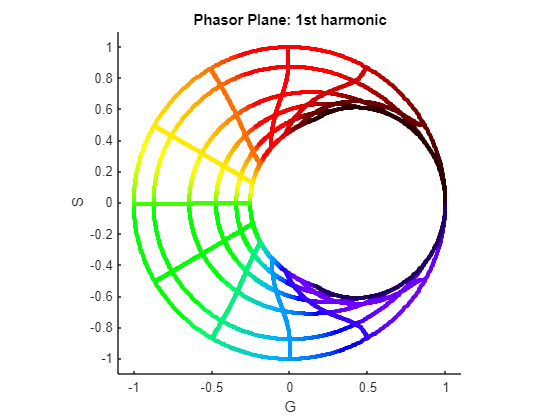

harmonic = 1;
sub_lambda = 0;
sigma = [0 25 45 60 75 90];

cerchio = ref_circle(lambda, harmonic, sub_lambda, sigma, 50);

figure;
scatter(cerchio.G, cerchio.S, 10, cerchio.colormap, 'filled');
xlabel("G")
ylabel('S')
axis square;
xlim([-1.1 1.1]);
ylim([-1.1 1.1]);
title('Phasor Plane: 1st harmonic')

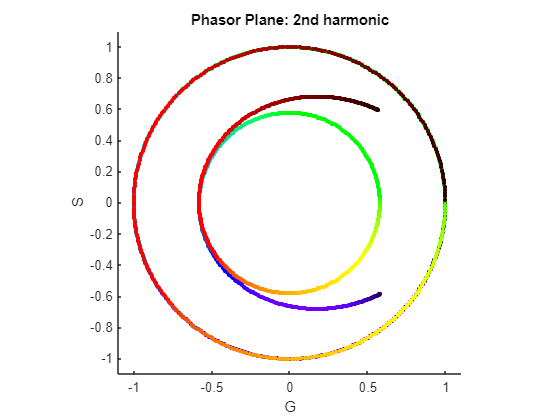


harmonic = 2;
sigma = [0 25];
cerchio = ref_circle(lambda, harmonic, sub_lambda, sigma, 0);

figure;
scatter(cerchio.G, cerchio.S, 10, cerchio.colormap, 'filled');
xlabel("G")
ylabel('S')
axis square;
xlim([-1.1 1.1]);
ylim([-1.1 1.1]);
title('Phasor Plane: 2nd harmonic')

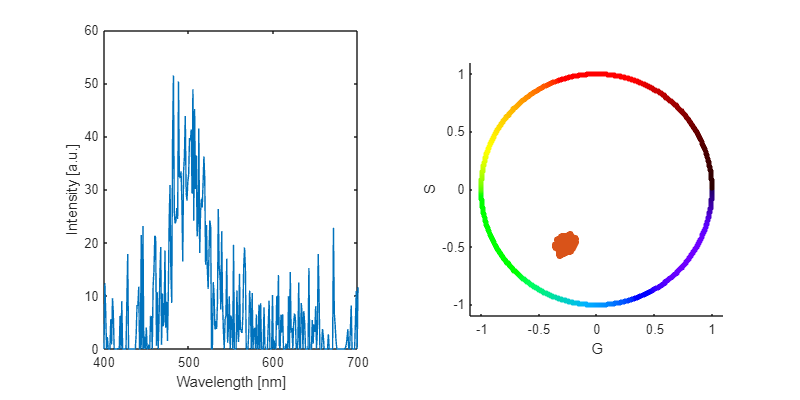

% RUMORE

wav_center =500;
sigma = 20;
SNR = 2;

spectra = zeros(numel(lambda), 2, 500);

for i = 1:size(spectra, 3)
    tmp_spectrum = squeeze(spectra(:,:,i));
    tmp_spectrum(:,1) = lambda;
    tmp_spectrum(:,2) = 0;
    tmp_spectrum = gaussian_n_noise(tmp_spectrum, 35, 0, wav_center, 0, sigma, 0, SNR);
    spectra(:,:,i) = tmp_spectrum;
end

figure("Position",[100 100 800 400]);
tiledlayout(1,2)
nexttile
i = randi(size(spectra,3));
plot(squeeze(spectra(:,1,i)),squeeze(spectra(:,2,i)))
xlabel("Wavelength [nm]")
ylabel("Intensity [a.u.]")
harmonic = 1;
phasors = zeros(size(spectra,3),2);

for i = 1:size(phasors,1)
    [G, S] = spectra_to_phasor(squeeze(spectra(:,1:2,i)), 1, 0);
    phasors(i,1) = G;
    phasors(i,2) = S;
end


nexttile
cerchio = ref_circle(lambda);
scatter(cerchio.G, cerchio.S, 15, cerchio.colormap, 'filled');
hold on;
xlabel("G")
ylabel('S')

xlim([-1.1 1.1])
ylim([-1.1 1.1])

axis square;
scatter(phasors(:,1), phasors(:,2), 'filled');

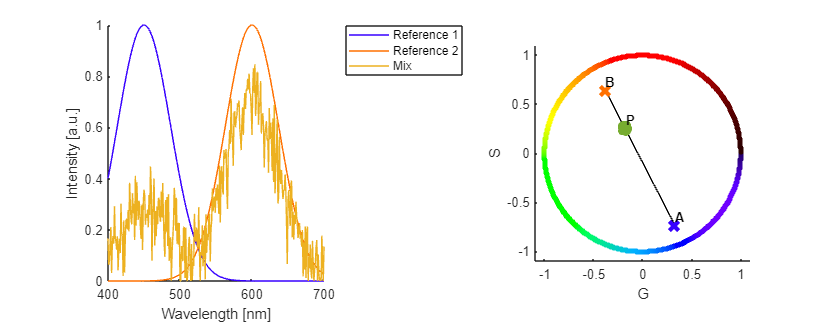

% DECONVOLUZIONE RETTA

mix_ratio = 0.3;
wavelength_ref_1 = 450;
wavelength_ref_2 = 600;
sigma_ref = 37;
SNR = 15;

ref_1 = zeros(numel(lambda), 2);
color_ref_1 = spectrumRGB(wavelength_ref_1);
ref_1(:,1) = lambda;
ref_1 = gaussian_n_noise(ref_1, 1, 0, wavelength_ref_1, 0, sigma_ref, 0, +Inf);
[G_ref_1, S_ref_1] = spectra_to_phasor(ref_1, 1, 0);
ref_1_phasors = [G_ref_1, S_ref_1];

ref_2 = zeros(numel(lambda), 2);
color_ref_2 = spectrumRGB(wavelength_ref_2);
ref_2(:,1) = lambda;
ref_2 = gaussian_n_noise(ref_2, 1, 0, wavelength_ref_2, 0, sigma_ref, 0, +Inf);
[G_ref_2, S_ref_2] = spectra_to_phasor(ref_2, 1, 0);
ref_2_phasors = [G_ref_2, S_ref_2];

spectra_mix = zeros(numel(lambda), 2, 500);

for i = 1:size(spectra_mix, 3)
    tmp_spectrum = squeeze(spectra_mix(:,:,i));
    tmp_spectrum(:,1) = lambda;
    tmp_spectrum(:,2) = 0;
    tmp_spectrum = gaussian_n_noise(tmp_spectrum, mix_ratio, 0, wavelength_ref_1, 0, sigma_ref, 0, SNR);
    tmp_spectrum = gaussian_n_noise(tmp_spectrum, 1-mix_ratio, 0, wavelength_ref_2, 0, sigma_ref, 0, SNR);
    spectra_mix(:,:,i) = tmp_spectrum;
end

figure("Position",[100 100 1000 400]);
tiledlayout(1,2)
nexttile
hold on
plot(ref_1(:,1),ref_1(:,2),'Color',color_ref_1);
plot(ref_2(:,1),ref_2(:,2),'Color',color_ref_2);
i = randi(size(spectra_mix,3));
plot(squeeze(spectra_mix(:,1,i)),squeeze(spectra_mix(:,2,i)))
legend('Reference 1', 'Reference 2', 'Mix', "Location","bestoutside")
xlabel("Wavelength [nm]")
ylabel("Intensity [a.u.]")


harmonic = 1;
phasors = zeros(size(spectra_mix,3),2);
for i = 1:size(phasors,1)
    [G, S] = spectra_to_phasor(squeeze(spectra_mix(:,1:2,i)), 1, 0);
    phasors(i,1) = G;
    phasors(i,2) = S;
end
mix_phasor = mean(phasors,1);

ax2 = nexttile;
hold on;
cerchio = ref_circle(lambda);
scatter(cerchio.G, cerchio.S, 15, cerchio.colormap, 'filled');

xlabel("G")
ylabel('S')
xlim([-1.1 1.1])
ylim([-1.1 1.1])
axis(ax2, "square");

plot([G_ref_1 G_ref_2], [S_ref_1 S_ref_2], 'linewidth', 1, 'Color', 'black');
plot(G_ref_1, S_ref_1,'x','MarkerSize', 10, 'Color', color_ref_1, 'LineWidth',3);
text(G_ref_1, S_ref_1, "A", 'VerticalAlignment','bottom','HorizontalAlignment','left', 'FontWeight','bold')
plot(G_ref_2, S_ref_2,'x','MarkerSize', 10, 'Color', color_ref_2, 'LineWidth',3);
text(G_ref_2, S_ref_2, "B",'VerticalAlignment','bottom','HorizontalAlignment','left', 'FontWeight','bold')

scatter(phasors(:,1), phasors(:,2), 'filled');
text(mix_phasor(1), mix_phasor(2), "P",'VerticalAlignment','bottom','HorizontalAlignment','left', 'FontWeight','bold')

fprintf(' AB: %.2f \n PA: %.2f \n PB: %.2f \n PB/AB: %.2f \n Original: %.2f', ...
    norm(ref_1_phasors-ref_2_phasors), ...
    norm(mix_phasor-ref_1_phasors), ...
    norm(mix_phasor-ref_2_phasors), ...
    norm(mix_phasor-ref_2_phasors) / norm(ref_1_phasors-ref_2_phasors), ...
    mix_ratio);

 AB: 1.55 
 PA: 1.11 
 PB: 0.43 
 PB/AB: 0.28 
 Original: 0.30

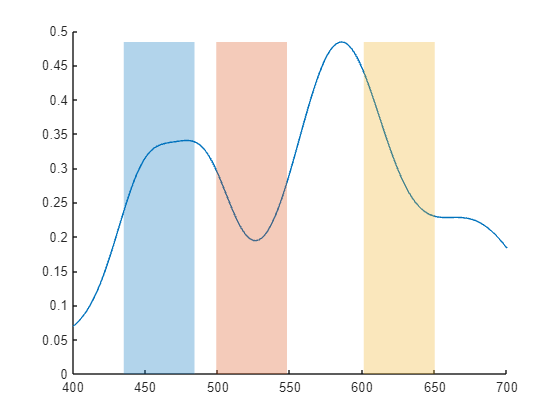

% FINESTRE

spectrum = zeros(numel(lambda),2);
spectrum(:,1) = lambda;
spectrum = gaussian_n_noise(spectrum, 0.2, 0, 450, 0, 20, 0, +Inf);
spectrum = gaussian_n_noise(spectrum, 0.1, 0, 500, 0, 100, 0, +Inf);
spectrum = gaussian_n_noise(spectrum, 0.4, 0, 585, 0, 30, 0, +Inf);
spectrum = gaussian_n_noise(spectrum, 0.2, 0, 490, 0, 20, 0, +Inf);
spectrum = gaussian_n_noise(spectrum, 0.2, 0, 677, 0, 40, 0, +Inf);

width_windows = 50;
num_windows = 3;

possible_starts = min(lambda):(max(lambda) - width_windows);
selected_starts = [];

while length(selected_starts) < num_windows
    candidate = randsample(possible_starts, 1);
    if all(abs(candidate - selected_starts) >= width_windows)
        selected_starts = [selected_starts, candidate];
    end
end

selected_starts = sort(selected_starts);
spectral_window = struct;

colormap_windows = lines(num_windows);

for i = 1:num_windows
    min_lambda = min(lambda(lambda >= selected_starts(i) & lambda < selected_starts(i) + width_windows));
    min_idx = find(lambda == min_lambda);
    max_lambda = max(lambda(lambda >= selected_starts(i) & lambda < selected_starts(i) + width_windows));
    max_idx = find(lambda == max_lambda);
    spectral_window(i).start_index = min_idx;
    spectral_window(i).end_index = max_idx;
    spectral_window(i).range = [min_lambda max_lambda];

    [G, S] = spectra_to_phasor(spectrum(min_idx:max_idx,:), 1, 0);
    spectral_window(i).phasors = [G,S];
    spectral_window(i).circle =  ref_circle(spectrum(min_idx:max_idx,1), harmonic);

    spectral_window(i).color = colormap_windows(i,:);

end


figure
hold on
plot(spectrum(:,1), spectrum(:,2));
for i = 1:num_windows
    fill(repelem(spectral_window(i).range,2), [0 max(spectrum(:,2)) max(spectrum(:,2)) 0], spectral_window(i).color, 'EdgeColor', 'none', 'FaceAlpha', 0.3);
end

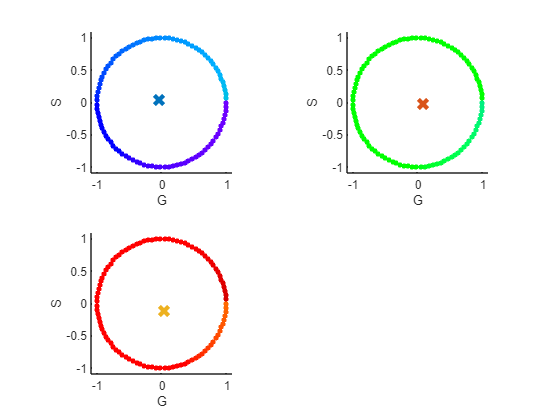

figure
tiledlayout('flow')
for i = 1:num_windows
    ax = nexttile;
    hold on;
    scatter(spectral_window(i).circle.G, spectral_window(i).circle.S, 15, spectral_window(i).circle.colormap, 'filled');
    plot(spectral_window(i).phasors(1), spectral_window(i).phasors(2),'x','MarkerSize', 10, 'Color', spectral_window(i).color, 'LineWidth',3);
    xlabel("G")
    ylabel('S')
    xlim([-1.1 1.1])
    ylim([-1.1 1.1])
    axis(ax, "square");
end